clc;
clear;
close all;

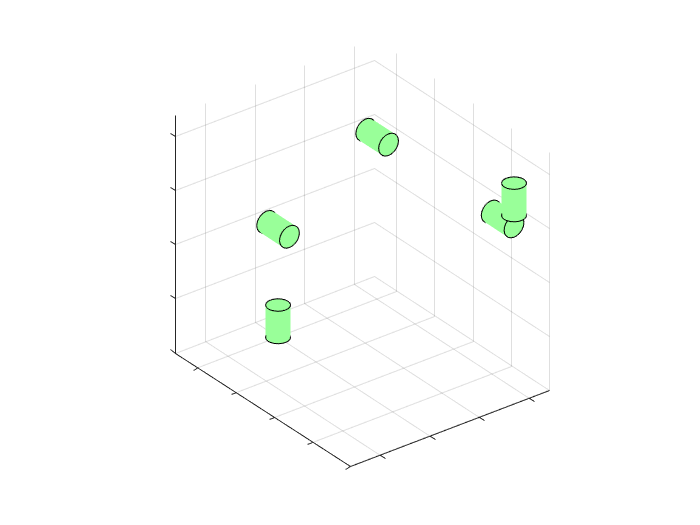

% Plot the structure of lynx arm using cylinders
radius = 1;
height = 3;

% define origins and orientations for each cylinder
origins = [0, 0, 0; 0, 1.5, 10,; 10, 1.5, 15; 10, -15, 15; 10, -18, 16]; % x,y,z co-ordinates for origin
orientations = [0, 0, 0; 0, 0, pi/2; 0, 0, pi/2; 0, 0, pi/2; 0, 0, 0]; % Euler angles for rotation

% Plot each cylinder with a loop
for i = 1:size(origins, 1)
    plot_oriented_cylinder(radius, height, origins(i, :), orientations(i, :));
end

axis equal;
xlim([-8, 12]);
ylim([-20, 3]); 
zlim([0, 22]); 
set(gca, 'XTickLabel', []);
set(gca, 'YTickLabel', []);
set(gca, 'ZTickLabel', []);

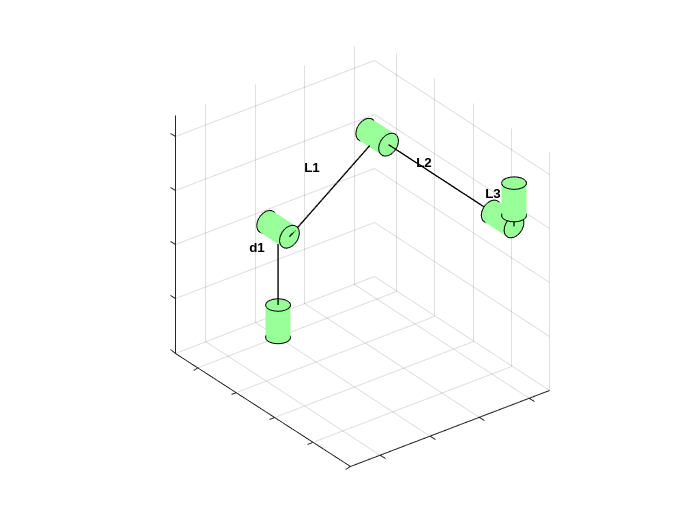

% Connect cylinders with lines
for i = 1:size(origins, 1)-1
    % Current cylinder's origin and orientation
    origin_current = origins(i, :);
    orientation_current = orientations(i, :);
    R_current = eul2rotm(orientation_current); % Rotation matrix for current cylinder

    % Calculate top center of the current cylinder
    start_point = origin_current + (R_current * [0; 0; height])';

    % Next cylinder's origin and orientation
    origin_next = origins(i+1, :);
    orientation_next = orientations(i+1, :);
    R_next = eul2rotm(orientation_next); % Rotation matrix for next cylinder

    % Calculate the top center point of the next cylinder
    top_center_next = origin_next + (R_next * [0; 0; height/2])';

    % Determine if the next cylinder is rotated by approximately pi/2
    if abs(orientation_current(1) - orientation_next(3) ) < 0 % z-axis rotation by pi/2
        % Adjust the end point to lie on the outer surface along the X-axis
        end_point = top_center_next + (R_next * [radius; 0; 0])';
    else
        % Default to top center if no significant rotation
        end_point = top_center_next;
    end

    % Plot line between the top center of the current cylinder and adjusted point on the next cylinder
    plot3([start_point(1), end_point(1)], ...
          [start_point(2), end_point(2)], ...
          [start_point(3), end_point(3)], ...
          'k', 'LineWidth', 1);

    % calculate the midpoint of the line for labeling
    midpoint = (start_point + end_point) / 2;

    % label based on the value of i
    if i == 1
        label = 'd1';
    else
        label = ['L', num2str(i-1)];
    end

    % label at the midpoint
    text(midpoint(1)-1, midpoint(2)+1.5, midpoint(3)+1.5, label, ...
        'HorizontalAlignment', 'center', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'k');

end

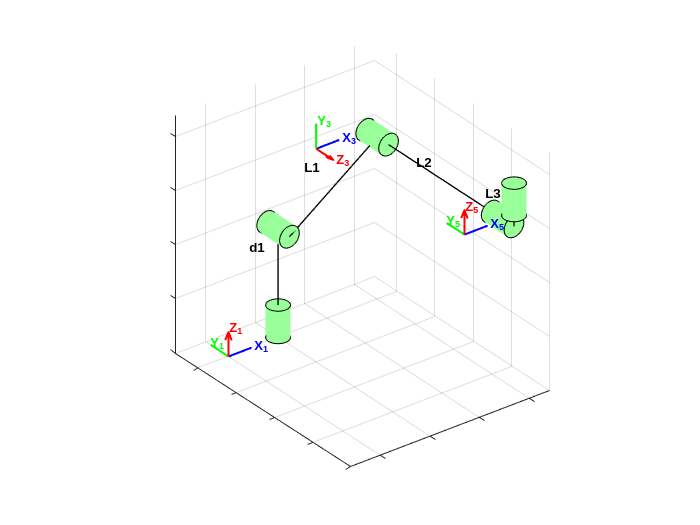

% frames cylinders (1st, 3rd, and 5th)
axis_length = 2.5; 
x_offset = 5;
for i = 1:size(origins, 1)
    if ismember(i, [1, 3, 5])
        % calculate rotation matrix from Euler angles
        R = eul2rotm(orientations(i, :));
        origin = origins(i, :);

        % apply the X-offset only when plotting the frame
        origin_offset = origin - [x_offset, 0, 0];

        % Plot each axis of the frame with offset applied
        quiver3(origin_offset(1), origin_offset(2), origin_offset(3), R(1,1)*axis_length, R(2,1)*axis_length, R(3,1)*axis_length, 'b', 'LineWidth', 1.5); % X-axis
        quiver3(origin_offset(1), origin_offset(2), origin_offset(3), R(1,2)*axis_length, R(2,2)*axis_length, R(3,2)*axis_length, 'g', 'LineWidth', 1.5); % Y-axis
        quiver3(origin_offset(1), origin_offset(2), origin_offset(3), R(1,3)*axis_length, R(2,3)*axis_length, R(3,3)*axis_length, 'r', 'LineWidth', 1.5, 'MaxHeadSize', 1.5); % Z-axis


        % Add axis labels X, Y, Z at the end of each axis with offset applied
        text(origin_offset(1) + R(1,1)*axis_length, origin_offset(2) + R(2,1)*axis_length, origin_offset(3) + R(3,1)*axis_length, ['X_', num2str(i)], 'Color', 'b', 'FontSize', 10, 'FontWeight', 'bold');
        text(origin_offset(1) + R(1,2)*axis_length, origin_offset(2) + R(2,2)*axis_length, origin_offset(3) + R(3,2)*axis_length, ['Y_', num2str(i)], 'Color', 'g', 'FontSize', 10, 'FontWeight', 'bold');
        text(origin_offset(1) + R(1,3)*axis_length, origin_offset(2) + R(2,3)*axis_length, origin_offset(3) + R(3,3)*axis_length, ['Z_', num2str(i)], 'Color', 'r', 'FontSize', 10, 'FontWeight', 'bold');
    end

end

% Save the current figure as a .png
% filename = 'lynx_arm.pdf';
% exportgraphics(gcf, filename, 'ContentType', 'vector');

syms theta1 theta2 theta3 theta4 theta5 d1 L1 L2 L3
T01 = dh_proximal(theta1, 0, 0, 0)

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = dh_proximal(theta2, d1, 0, pi/2)

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & -1 & -d_{1}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = dh_proximal(theta3, 0, L1, 0)

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{1}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34 = dh_proximal(theta4, 0, L2, 0)

$$T34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & L_{2}\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T45 = dh_proximal(theta5, L3, 0, -pi/2)

$$T45 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 1 & L_{3}\\ -\sin\left(\theta_{5}\right) & -\cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%calculate forward kinematic matrix (part1)
T35 = T34 * T45

$$T35 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right) & -\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & -\sin\left(\theta_{4}\right) & L_{2}-L_{3}\,\sin\left(\theta_{4}\right)\\ \cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & \cos\left(\theta_{4}\right) & L_{3}\,\cos\left(\theta_{4}\right)\\ -\sin\left(\theta_{5}\right) & -\cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%calculate forward kinematic matrix (part1)
T06 = T01 * T12 * T23 * T34 * T45

% Known values
theta1_val = 0;
theta2_val = 0;

% Substitute the known values into the matrix
%T30_evaluated = subs(T30, {theta1, theta2}, {theta1_val, theta2_val})